# Particiones de un número

#### Calcular número de particiones y animación:

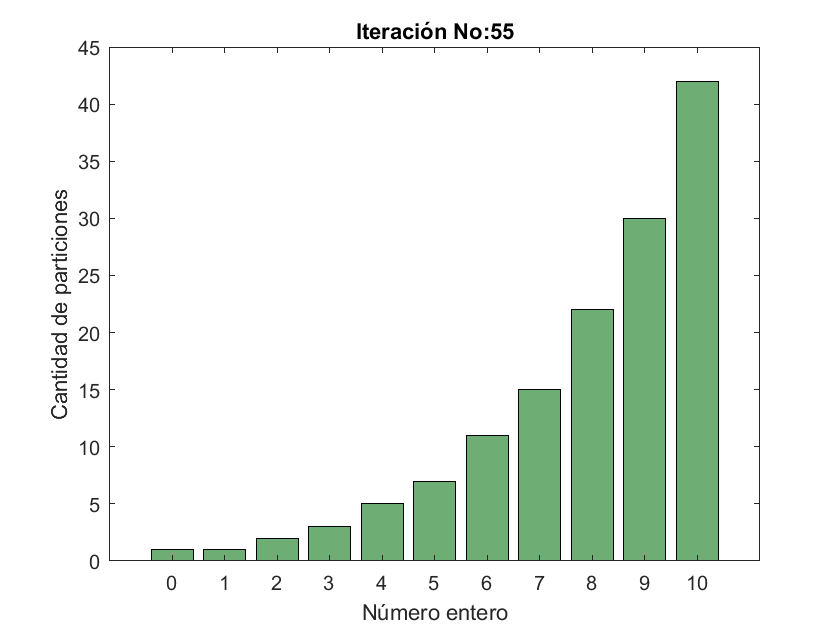

clear;clc;close
counter = 0;
iterationNumber=10;
iterationVector = zeros(1,iterationNumber+1);
iterationVector(1)=1;
xAxisVector = 0:1:length(iterationVector)-1;
for iteration=2:1:length(iterationVector)
    tempIndexList = iteration:length(iterationVector);
    for tempValue = 1:1:length(tempIndexList)
        counter = counter+1;
        iterationVector(tempIndexList(tempValue)) = iterationVector(tempIndexList(tempValue)) + ...
                                                    iterationVector(tempValue);        
         bar(xAxisVector,iterationVector,'FaceColor', [.43 .68 .45])
         title(['Iteración No:',num2str(counter)])
         xlabel( 'Número entero', 'Interpreter', 'none' );
         ylabel( 'Cantidad de particiones', 'Interpreter', 'none' );
         pause(0.001)
    end
end

#### Número de iteraciones por número:

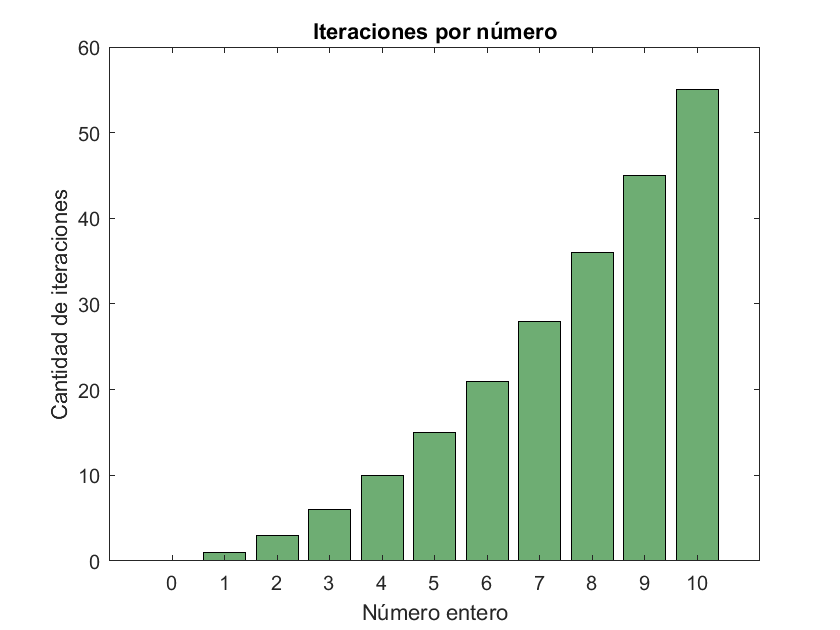

numberOfIteration=[];
for j=0:1:iterationNumber
    [resultList, tempCounter] = PartitionNumber(j);
    numberOfIteration = [numberOfIteration tempCounter];
end
bar(xAxisVector,numberOfIteration,'FaceColor', [.43 .68 .45]);
title('Iteraciones por número')
xlabel( 'Número entero', 'Interpreter', 'none' );
ylabel( 'Cantidad de iteraciones', 'Interpreter', 'none' );

#### Aproximación de los resultados a funciones:

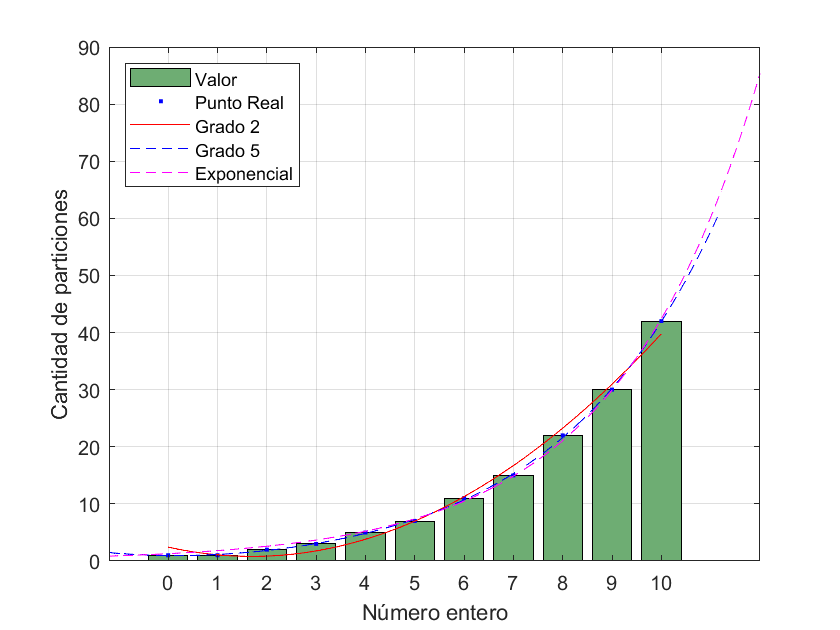

[xData, yData] = prepareCurveData( xAxisVector, iterationVector);

fitType1 = fittype( 'poly2' );
fitType2 = fittype( 'poly5' );
fitType3 = fittype( 'exp1' );

[fitResultPoly2, gof1] = fit( xData, yData, fitType1);
[fitResultPoly5, gof2] = fit( xData, yData, fitType2);
[fitResultExp1, gof3] = fit( xData, yData, fitType3);


bar(xAxisVector,iterationVector,'FaceColor', [.43 .68 .45])
hold on
plot( fitResultPoly2, xData, yData);
legend('Location','NorthWest');
plot( fitResultPoly5,'b--');
plot( fitResultExp1, 'm--');
hold off
legend('Valor','Punto Real', 'Grado 2', 'Grado 5','Exponencial')
xlabel( 'Número entero', 'Interpreter', 'none' );
ylabel( 'Cantidad de particiones', 'Interpreter', 'none' );
grid on